% Multivariate model for 
% Y1=son height, Y2=daughter height
% X1 = father height, X2=mother height
clear all
close all
rng('default')
% define true parameter values
n=100;
B=[[14.1;0.41;0.43],[10.8;0.39;0.43]]

B =    14.1000   10.8000
    0.4100    0.3900
    0.4300    0.4300


sigma1=1.5; 
sigma2=1.5; 
rho=0.5;
Sigma=[sigma1^2,sigma1*sigma2*rho;sigma1*sigma2*rho,sigma2^2]

Sigma =     2.2500    1.1250
    1.1250    2.2500


A=chol(Sigma)'

A =     1.5000         0
    0.7500    1.2990


% generate simulated data
hf=(66:66+9);
hm=(60:60+9);
[Xf,Xm]=meshgrid(hf,hm);
xf=reshape(Xf,n,1);
xm=reshape(Xm,n,1);
X=[ones(n,1),xf,xm]

X =      1    66    60
     1    66    61
     1    66    62
     1    66    63
     1    66    64
     1    66    65
     1    66    66
     1    66    67
     1    66    68
     1    66    69


E=(A*randn(2,n))'; 
Y=X*B+E

Y =    67.7665   65.1255
   64.0017   62.1959
   68.2981   61.7403
   67.5996   63.7499
   74.0476   70.3414
   67.0852   67.4201
   70.6281   65.3821
   71.0421   65.6198
   70.2138   67.6221
   72.9436   69.1078



replicate=10000;
X=repmat(X,replicate,1)

X =      1    66    60
     1    66    61
     1    66    62
     1    66    63
     1    66    64
     1    66    65
     1    66    66
     1    66    67
     1    66    68
     1    66    69


m=size(X,1);
E=(A*randn(2,m))';
Y=X*B+E

Y =    67.2348   61.1397
   68.8138   63.8808
   68.0228   63.9707
   68.6421   62.6030
   68.4365   63.7485
   68.3120   66.2761
   68.2264   63.6347
   68.9020   63.2907
   70.1116   65.2798
   73.1251   67.0341


X=permute(reshape(X', [3,n,replicate]), [2, 1, 3]);
Y=permute(reshape(Y', [2,n,replicate]), [2, 1, 3]);

Bhat=zeros(3,2,replicate);
SigmaHat=zeros(2,2,replicate);
% Estimate parameters

for j=1:replicate
    Bhat(:,:,j)=inv(X(:,:,j)'*X(:,:,j))*X(:,:,j)'*Y(:,:,j);
end

for j=1:replicate
    SigmaHat(:,:,j)=(Y(:,:,j)-X(:,:,j)*B)'*(Y(:,:,j)-X(:,:,j)*B)/(n-3);    
end

bhat=Bhat

bhat = bhat(:,:,1) =

   22.7368   13.3973
    0.3605    0.4266
    0.3483    0.3468


bhat(:,:,2) =

   11.9682    9.3235
    0.4486    0.4015
    0.4222    0.4410


bhat(:,:,3) =

   15.8619   12.9314
    0.4134    0.3703
    0.3988    0.4159


bhat(:,:,4) =

    5.8404   -3.0074
    0.5114    0.5265
    0.4479    0.4921


bhat(:,:,5) =

   14.4922   10.8140
    0.4101    0.3328
    0.4272    0.4931


bhat(:,:,6) =

   22.0028   18.3524
    0.3544    0.3412
    0.3738    0.3719


bhat(:,:,7) =

   12.0040    8.0542
    0.4019    0.3953
    0.4701    0.4635


bhat(:,:,8) =

   14.6578   10.9879
    0.3968    0.3458
    0.4366    0.4753


bhat(:,:,9) =

   11.2781    9.8230
    0.4488    0.4324
    0.4314    0.4001


bhat(:,:,10) =

   14.6345   19.4263
    0.4128    0.3383
    0.4201    0.3576


bhat(:,:,11) =

   17.5571    7.6807
    0.3930    0.4500
    0.3937    0.4108


bhat(:,:,12) =

   10.8264    7.6300
    0.4230    0.4115
    0.4674    0.4555


bhat(:,:,13) =

   19.9024   1

sigma=SigmaHat

sigma = sigma(:,:,1) =

    2.3298    1.0356
    1.0356    2.0417


sigma(:,:,2) =

    1.9358    1.1972
    1.1972    2.1677


sigma(:,:,3) =

    2.1842    1.4567
    1.4567    2.7582


sigma(:,:,4) =

    2.4767    1.3614
    1.3614    2.4164


sigma(:,:,5) =

    2.5984    1.2012
    1.2012    2.3421


sigma(:,:,6) =

    1.9520    1.2737
    1.2737    2.4620


sigma(:,:,7) =

    2.4635    1.5835
    1.5835    2.8063


sigma(:,:,8) =

    2.6412    1.3464
    1.3464    2.1926


sigma(:,:,9) =

    2.4280    1.2562
    1.2562    2.1293


sigma(:,:,10) =

    2.3463    1.2970
    1.2970    2.4699


sigma(:,:,11) =

    2.2899    0.8734
    0.8734    1.8046


sigma(:,:,12) =

    2.9464    1.4202
    1.4202    2.1787


sigma(:,:,13) =

    2.1039    1.0752
    1.0752    2.1900


sigma(:,:,14) =

    1.7666    0.7031
    0.7031    2.8684


sigma(:,:,15) =

    2.6731    1.1847
    1.1847    2.1489


sigma(:,:,16) =

    2.1405    1.0961
    1.0961    2.1302


sigma(:,:,17) =

    1.89


Mean_Bhat=mean(Bhat,3)

Mean_Bhat =    14.0499   10.8477
    0.4108    0.3899
    0.4299    0.4294


Mean_SigmaHat=mean(SigmaHat,3)

Mean_SigmaHat =     2.3199    1.1554
    1.1554    2.3159




Var_bhat=[var(Bhat(1,1,:),0) var(Bhat(1,2,:),0);
    var(Bhat(2,1,:),0) var(Bhat(2,2,:),0);
    var(Bhat(3,1,:),0) var(Bhat(3,2,:),0)]

Var_bhat =    24.8651   25.1005
    0.0027    0.0027
    0.0027    0.0028



Var_sigma=[var(SigmaHat(1,1,:),0) var(SigmaHat(1,2,:),0);
    var(SigmaHat(2,1,:),0) var(SigmaHat(2,2,:),0);]

Var_sigma =     0.1091    0.0672
    0.0672    0.1071


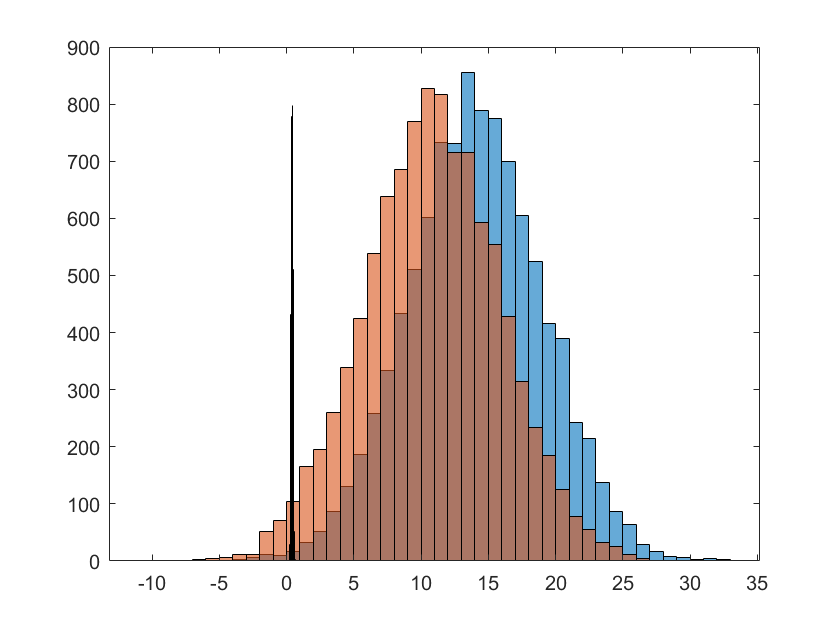


histogram(Bhat(1,1,:))
hold on
histogram(Bhat(1,2,:))
histogram(Bhat(2,1,:))
histogram(Bhat(2,2,:))
histogram(Bhat(3,1,:))
histogram(Bhat(3,2,:))
hold off

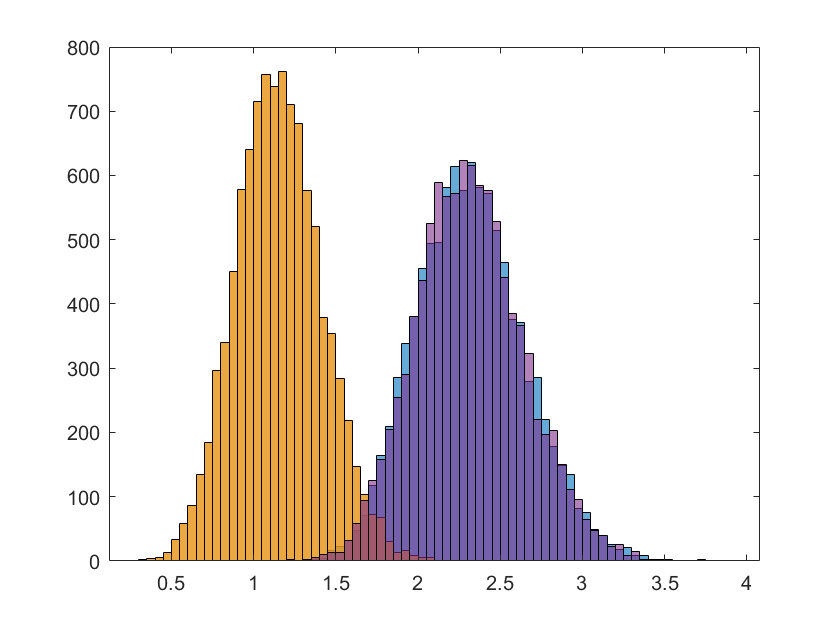



histogram(SigmaHat(1,1,:))
hold on
histogram(SigmaHat(1,2,:))
histogram(SigmaHat(2,1,:))
histogram(SigmaHat(2,2,:))
hold off

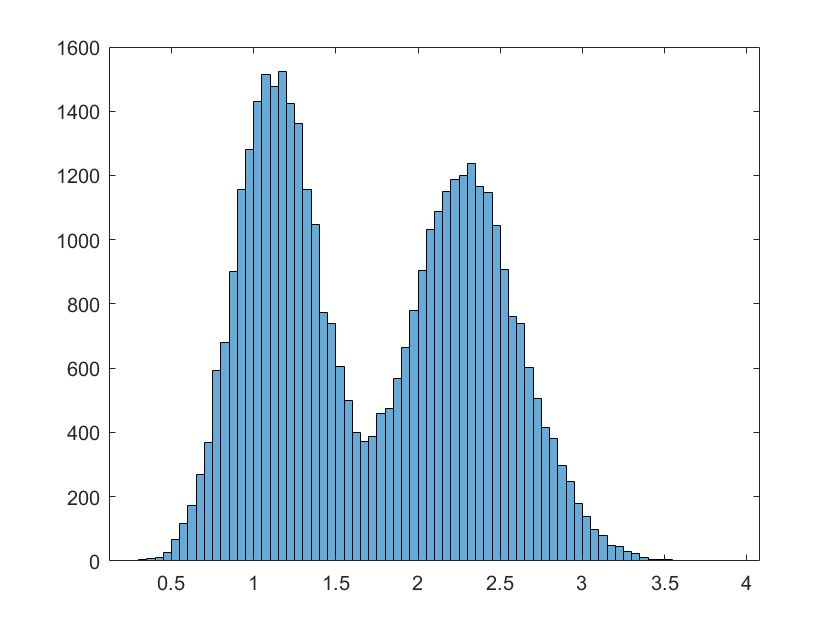


histogram(SigmaHat)